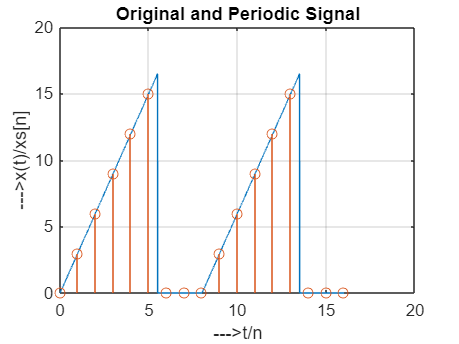

clc;close all;clear;

Original Signal

t=0:0.001:16;

x = zeros(1, length(t));
for i=1:length(t)
    if(t(i)>0 && t(i)<5.5)%         1st cycle
        x(i)=3*t(i);
    elseif(t(i)>8 && t(i)<13.5)%    2nd cycle
        x(i)=3*(t(i)-8);
    end
end

plot(t,x);%    original signal plot
hold on;

Periodic Signal

n=0:16;

xs = zeros(1, length(n));
for i=1:length(n)
    if(n(i)>0 && n(i)<6)%           1st cycle
        xs(i)=3*n(i);
    elseif(n(i)>8 && n(i)<14)%      2nd cycle
        xs(i)=3*(n(i)-8);
    end
end


stem(n,xs);%    periodic signal plot
grid on;
xlabel('--->t/n');ylabel('--->x(t)/xs[n]');
title('Original and Periodic Signal');